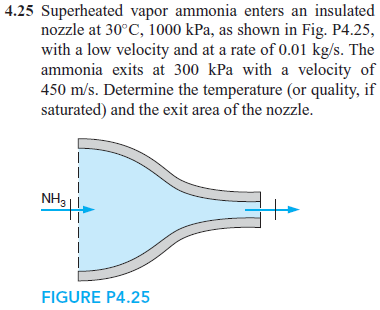

# mass flow rate

u = symunit;
mdot = 0.01*u.kg/u.s;

# inflow state (superheated vapor ammonia)

% --------------------
% given
p1 = 1000*u.kPa;
T1 = 30*u.Celsius;
V1 = 0;
% --------------------
% specific enthalpy
h1 = 1479.1*u.kJ/u.kg;
% --------------------

# outflow state

% --------------------
% given
p2 = 300*u.kPa;
V2 = 450*u.m/u.s;
% --------------------
% first law of thermodynamics
h2 = rewrite(solve(h1+V1^2/2 == sym('h2')+V2^2/2), u.kJ/u.kg);
h2_vpa = vpa(h2)

$$h2\_vpa = 1377.85\,\frac{\mathrm{kJ}}{\mathrm{kg}}$$

% --------------------
% quality
hf2 = interp1([290.9 354.9], [134.41 157.31], double(removeUnits(p2)))*u.kJ/u.kg;
hfg2 = interp1([290.9 354.9], [1296.4 1279.4], double(removeUnits(p2)))*u.kJ/u.kg;
x2 = (h2-hf2)/hfg2;
x2_vpa = vpa(x2, 3)

$$x2\_vpa = 0.958$$

% --------------------
% quality
vf2 = interp1([290.9 354.9], [0.001534 0.001550], double(removeUnits(p2)))*u.m^3/u.kg;
vfg2 = interp1([290.9 354.9], [0.41655 0.34493], double(removeUnits(p2)))*u.m^3/u.kg;
v2 = vf2+x2*vfg2;
v2_vpa = vpa(v2, 3)

$$v2\_vpa = 0.391\,\frac{m^{3}}{\mathrm{kg}}$$

% --------------------
% exit area
A2 = rewrite(solve(mdot == sym('A2')*V2/v2), u.mm);
A2_vpa = vpa(A2, 3)

$$A2\_vpa = 8.69\,{\mathrm{mm}}^{2}$$

% --------------------